# Laborator 6

## Problema 1

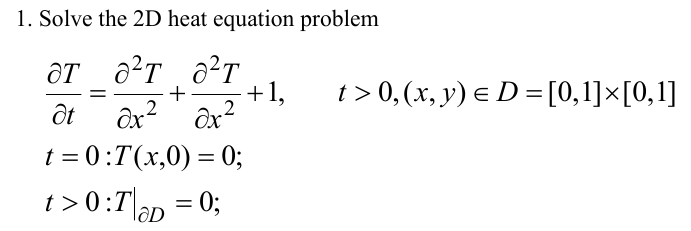

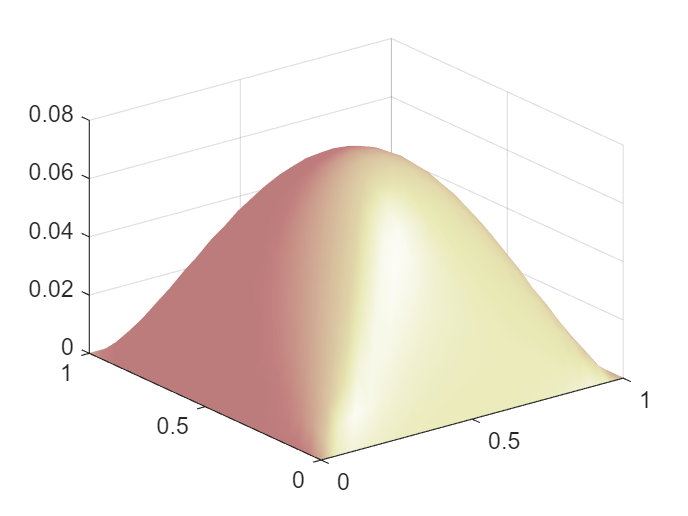

N=21; 
dx=1/(N-1); 
dt=dx*dx/10; 
niu=dt/dx/dx;
t_final=1;

Told=zeros(N,N);
Tnew=zeros(N,N);

nr_it=0; 
t=0;
while (t<t_final)
    t=t+dt;
    nr_it=nr_it+1;
    for i=2:N-1
        for j=2:N-1
            Tnew(i,j)=Told(i,j)+niu*(Told(i+1,j)-2*Told(i,j)+Told(i-1,j))+...
                niu*(Told(i,j+1)-2*Told(i,j)+Told(i,j-1))+dt;
        end
    end
    Told=Tnew;
    
    
end
    
figure(1)
surfl(0:dx:1,0:dx:1, Tnew);
shading interp;                       
colormap(pink);          
axis('on');

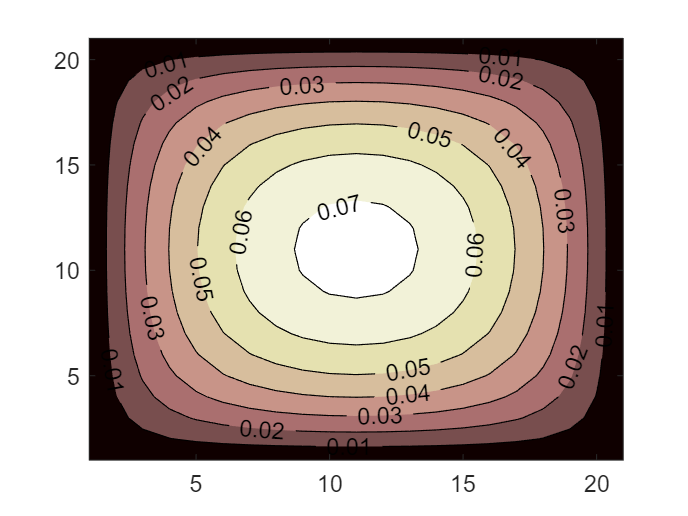

figure(2)
[c,h] = contourf(Tnew);
        clabel(c,h)
colormap(pink); 

## Problema 2

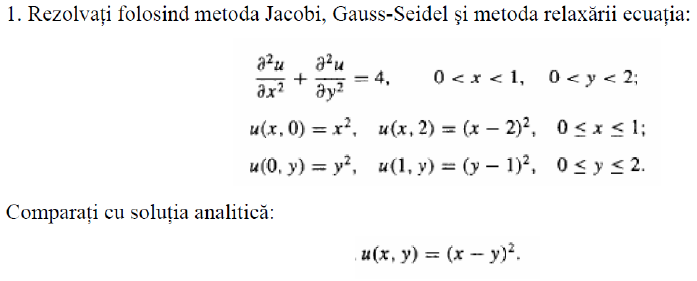

tic
format long

Nx=101; 
Ny=201; 
h=1/(Nx-1);
x=0:h:(Nx-1)*h;y=0:h:(Ny-1)*h;

u=zeros(Nx,Ny);
u_ex=u;
%conditii pe frontiera
u(:,1)=x.^2; u(:,Ny)=(x-2).^2;
u(1,:)=y.^2; u(Nx,:)=(y-1).^2;
u_new=u;

%% Metoda Jacobi
nr_it=0;    
stop=0;
while (stop~=1)
    nr_it=nr_it+1;
    
     err_u=0;  
    for i=2:Nx-1
        for j=2:Ny-1
            u_new(i,j)=0.25*(u(i+1,j)+u(i-1,j)+u(i,j+1)+u(i,j-1)-4*h*h);
            if abs(u(i,j)-u_new(i,j))>err_u 
                err_u=abs(u(i,j)-u_new(i,j));
            end
                     
        end
    end
     if err_u<1e-6
            stop=1;
     end
        
    u=u_new; 
end
for i=1:Nx
    for j=1:Ny
        u_ex(i,j)=((i-1)*h-(j-1)*h)^2;
    end
end

nr_it

nr_it =        17838


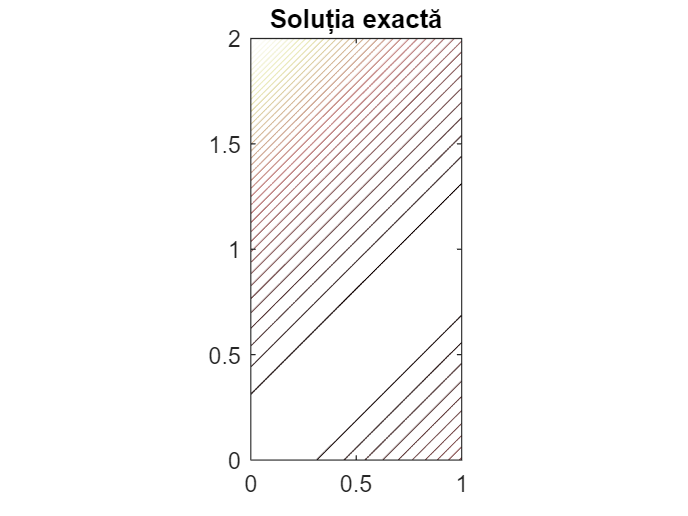


[C,H]=contour(x,y,u_ex',40);
title('Soluția exactă')
axis equal
axis([0,1,0,2])

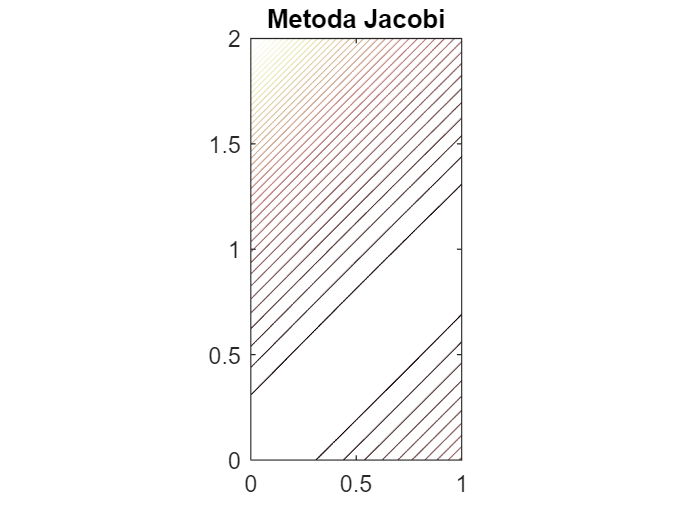

[C,H]=contour(x,y,u',40);
title('Metoda Jacobi')
axis equal
axis([0,1,0,2])


u=zeros(Nx,Ny);
u(:,1)=x.^2; u(:,Ny)=(x-2).^2;
u(1,:)=y.^2; u(Nx,:)=(y-1).^2;
u_new=u;

%%%%Metoda Gauss-Seidel
nr_it=0;    
stop=0;
while (stop~=1)
    nr_it=nr_it+1;
    
     err_u=0;  
    for i=2:Nx-1
        for j=2:Ny-1
            u_new(i,j)=0.25*(u(i+1,j)+u_new(i-1,j)+u(i,j+1)+u_new(i,j-1)-4*h*h);
            if abs(u(i,j)-u_new(i,j))>err_u 
                err_u=abs(u(i,j)-u_new(i,j));
            end
                     
        end
    end
     if err_u<1e-6
            stop=1;
     end
        
    u=u_new;
end

nr_it

nr_it =        10050


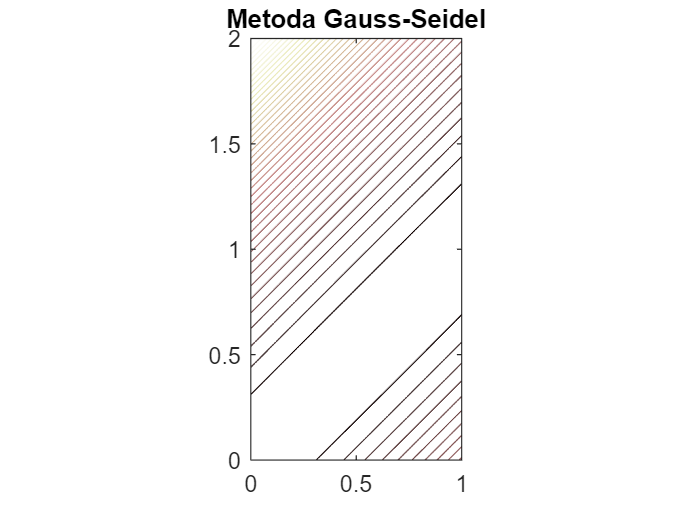


[C,H]=contour(x,y,u',40);
title('Metoda Gauss-Seidel')
axis equal
axis([0,1,0,2])


u=zeros(Nx,Ny);
u(:,1)=x.^2; u(:,Ny)=(x-2).^2;
u(1,:)=y.^2; u(Nx,:)=(y-1).^2;
u_new=u;

%%%%%Metoda relaxării
k=0;
nr_it=0;    
stop=0;
relax=1.95;
while (stop~=1)
    nr_it=nr_it+1;
    
     err_u=0;  
    for i=2:Nx-1
        for j=2:Ny-1
            u_new(i,j)=(1-relax)*u(i,j)+relax*0.25*(u(i+1,j)+u_new(i-1,j)+u(i,j+1)+u_new(i,j-1)-4*h*h);
            if abs(u(i,j)-u_new(i,j))>err_u 
                err_u=abs(u(i,j)-u_new(i,j));
            end
        end
    end
     if err_u<1e-6
            stop=1;
     end
        
    u=u_new; 
end

nr_it

nr_it =    372


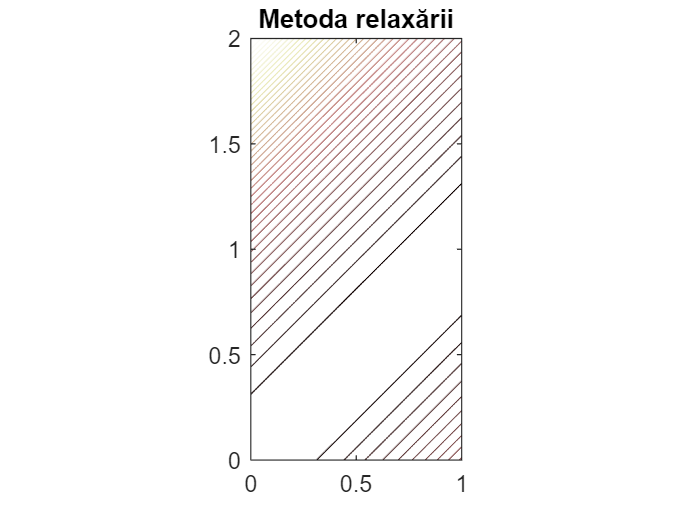


[C,H]=contour(x,y,u',40);
title('Metoda relaxării')
axis equal
axis([0,1,0,2])